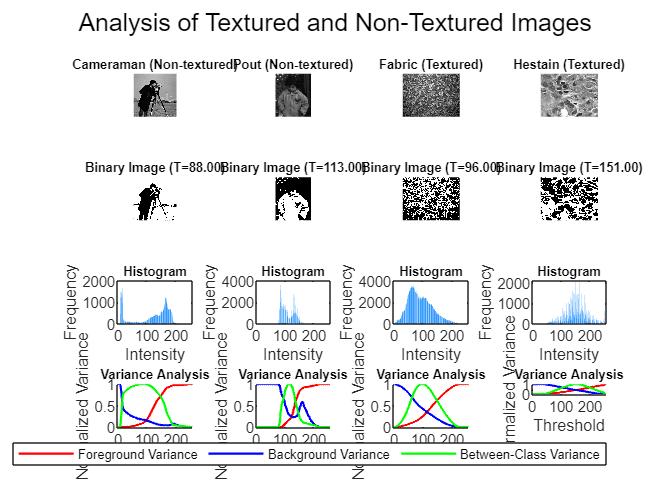

clc;
clear all;
close all;


titleFontSize = 7;
% READ IMAGES
% Non-textured image
image_one = imread("cameraman.tif");
image_two = imread("pout.tif");
% Textured image
image_three = rgb2gray(imread("fabric.png"));
image_four = rgb2gray(imread("hestain.png"));

% Store images in array for easier accessibility, include titles
images = {image_one, image_two, image_three, image_four};
titles = {'Cameraman (Non-textured)', 'Pout (Non-textured)', ...
          'Fabric (Textured)', 'Hestain (Textured)'};

% Initialize figure for analysis
figure('Name', 'Image Thresholding and Variance Analysis', 'NumberTitle', 'off');

for i = 1:length(images)
    img = images{i};

    % STEP 1: Compute Otsu's threshold
    otsuThreshold = graythresh(img) * 255; % Threshold, converts the threshold value from 0 or 1 to a value between 0 to 255
    binaryImg = imbinarize(img, otsuThreshold / 255); % Normalize threshold
    % A binary image has pixel values of 0 (black) for background and 1 (white) for foreground.
    % The imbinarize function uses "otsuThreshold" to classify each pixel:
    %Pixels with intensity greater than or equal to "otsuThreshold" are set to 1 (white).
    %Pixels with intensity less than "otsuThreshold" are set to 0 (black).

    % STEP 2: Make the histogram for each respective image and collect the
    % total amount of pixels 
    histvals = imhist(img);
    totalPixels = numel(img);

    % Initialize arrays
    var_fg = zeros(256, 1); % Variance foreground
    var_bg = zeros(256, 1); % Variance background
    var_between = zeros(256, 1); % Variance between
    w0 = zeros(256, 1); % First weight
    w1 = zeros(256, 1); % Second weight
    mu0 = zeros(256, 1); % First mean
    mu1 = zeros(256, 1); % Second mean

    for t = 1:256 %do the following for each pixel value
        % STEP 3: Compute the weights
        w0(t) = sum(histvals(1:t)) / totalPixels; % Foreground weight
        w1(t) = sum(histvals(t+1:end)) / totalPixels; % Background weight

        % Compute means
        if w0(t) > 0
            mu0(t) = sum((0:t-1)' .* histvals(1:t)) / sum(histvals(1:t));
        end
        if w1(t) > 0
            mu1(t) = sum((t:255)' .* histvals(t+1:end)) / sum(histvals(t+1:end));
        end

        % Compute variances
        var_fg(t) = sum(((0:t-1)' - mu0(t)).^2 .* histvals(1:t)) / (w0(t) * totalPixels + eps);
        var_bg(t) = sum(((t:255)' - mu1(t)).^2 .* histvals(t+1:end)) / (w1(t) * totalPixels + eps);
        var_between(t) = w0(t) * w1(t) * (mu0(t) - mu1(t))^2;
    end

    % Normalize variances for visualization
    var_fg_norm = var_fg / max(var_fg);
    var_bg_norm = var_bg / max(var_bg);
    var_between_norm = var_between / max(var_between);

    % Plot Original Image (First Row)
    subplot(4, 4, i);
    imshow(img, []);
    title(titles{i}, 'Interpreter', 'none', 'FontSize', titleFontSize);

    % Plot Binary Image (Second Row)
    subplot(4, 4, i+4);
    imshow(binaryImg, []);
    title(sprintf('Binary Image (T=%.2f)', otsuThreshold), 'FontSize', titleFontSize);

    % Plot Histogram (Third Row)
    subplot(4, 4, i+8);
    bar(histvals, 'FaceColor', [0.2, 0.6, 1], 'EdgeColor', 'none');
    title('Histogram','FontSize', titleFontSize);
    xlabel('Intensity');
    ylabel('Frequency');

    % Plot Variance Analysis (Fourth Row)
    subplot(4, 4, i+12);
    hold on;
    plot(var_fg_norm, 'r', 'LineWidth', 1.2); % Normalized Foreground Variance
    plot(var_bg_norm, 'b', 'LineWidth', 1.2); % Normalized Background Variance
    plot(var_between_norm, 'g', 'LineWidth', 1.2); % Normalized Between-Class Variance
    hold off;
    title('Variance Analysis', 'FontSize', titleFontSize);
    xlabel('Threshold');
    ylabel('Normalized Variance');
end

% Add a single legend outside the figure for variance plots
legend({'Foreground Variance', 'Background Variance', 'Between-Class Variance'}, ...
    'FontSize', 7, 'Location', 'southoutside', 'Orientation', 'horizontal');

% Add a global title
sgtitle('Analysis of Textured and Non-Textured Images');